%**************************************************************************
% 
% Copyright (C) 2020, Jaein Lim and Panagiotis Tsiotras
% 
% 
% This library is free software; you can redistribute it and/or modify it under
% the terms of the GNU Lesser General Public License as published by the Free
% Software Foundation; either version 2.1 of the License, or any later version.
% 
% This library is distributed in the hope that it will be useful, but WITHOUT
% ANY WARRANTY;  without even the implied warranty of MERCHANTABILITY or
% FITNESS FOR A PARTICULAR PURPOSE. See the GNU Lesser General Public License
% for more details.
% 
% You should have received a copy of the GNU Lesser General Public License
% along with this library; if not, write to the Free Software Foundation, Inc.,
% 51 Franklin Street, Fifth Floor, Boston, MA 02110-1301 USA
% 
%**************************************************************************/



close all
clear all
clc

## Setting

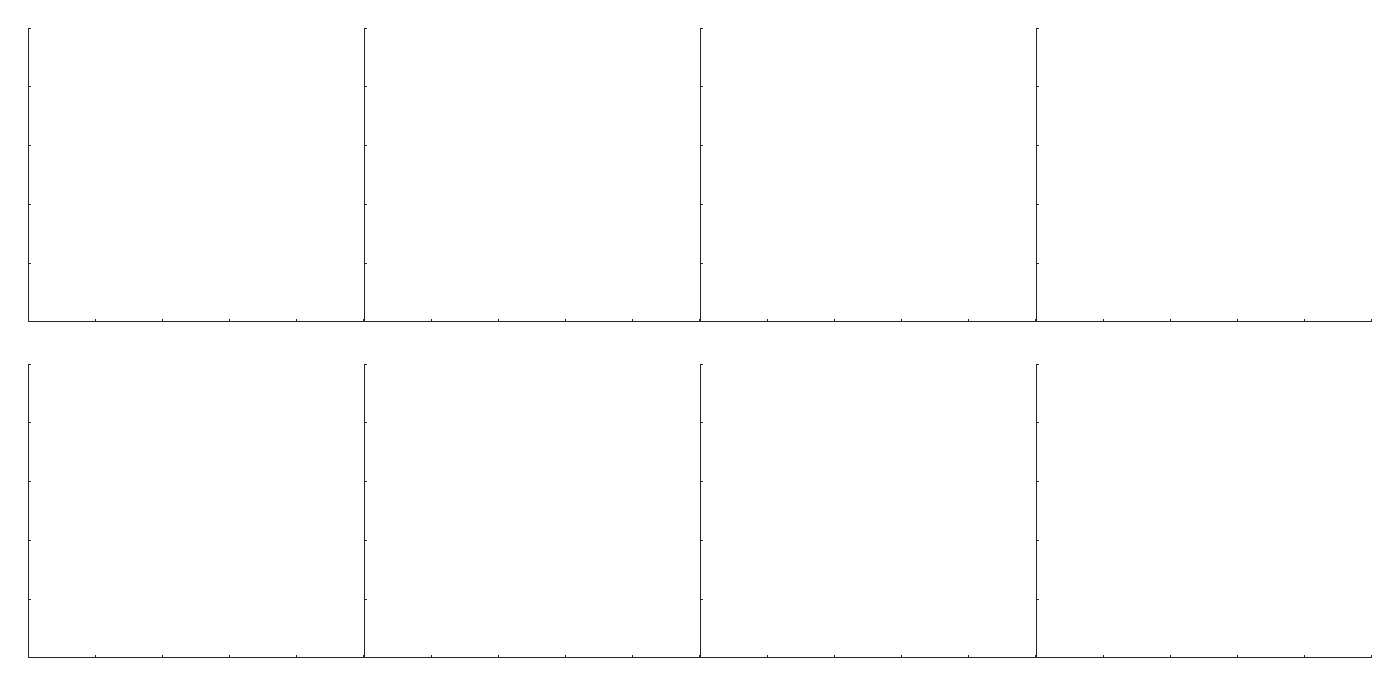

drawPath =1;
drawPrePath = 0;
drawValue = 1;
drawEdge = 0;
drawText = 0; 


drawPostSearch = 1;
pdfy = 1;
agent_number =4;

% for agent_i=1:agent_number
%  
%     result_file_name = ['instance/result', num2str(agent_i),'.txt'];        
%     result = load(result_file_name);
%     fprintf('------------ Agent%d -------------\n', agent_i);
%     fprintf('       # processed msg: %d \n', result(1));
%     fprintf('       # expanded vertex: %d \n', result(2));
% end


color_bit=64; % will sort values into #color_bit bins 
color_bar = flip(gray(color_bit)); %name of colormap :gray, spring, winter, default,... 

if(pdfy)
    h = figure('Position', [1800 1800 350*agent_number 700]);
     h.Renderer='Painters';
    set(h,'Units','Inches');
    pos = get(h,'Position');
    set(h,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])
    
    if (drawPostSearch)
    [ha, pos2] = tight_subplot(2, agent_number,[0.06 0],[.06 .04],[0.02 0.02]) ;
    else
     [ha, pos2] = tight_subplot(1, agent_number,[0.06 0.06],[.06 .04],[0.02 0.02]) ;    
    end
    
else
    h = figure('Position', [1800 1800 1200 1200]);
end

%original path A

## Presearch

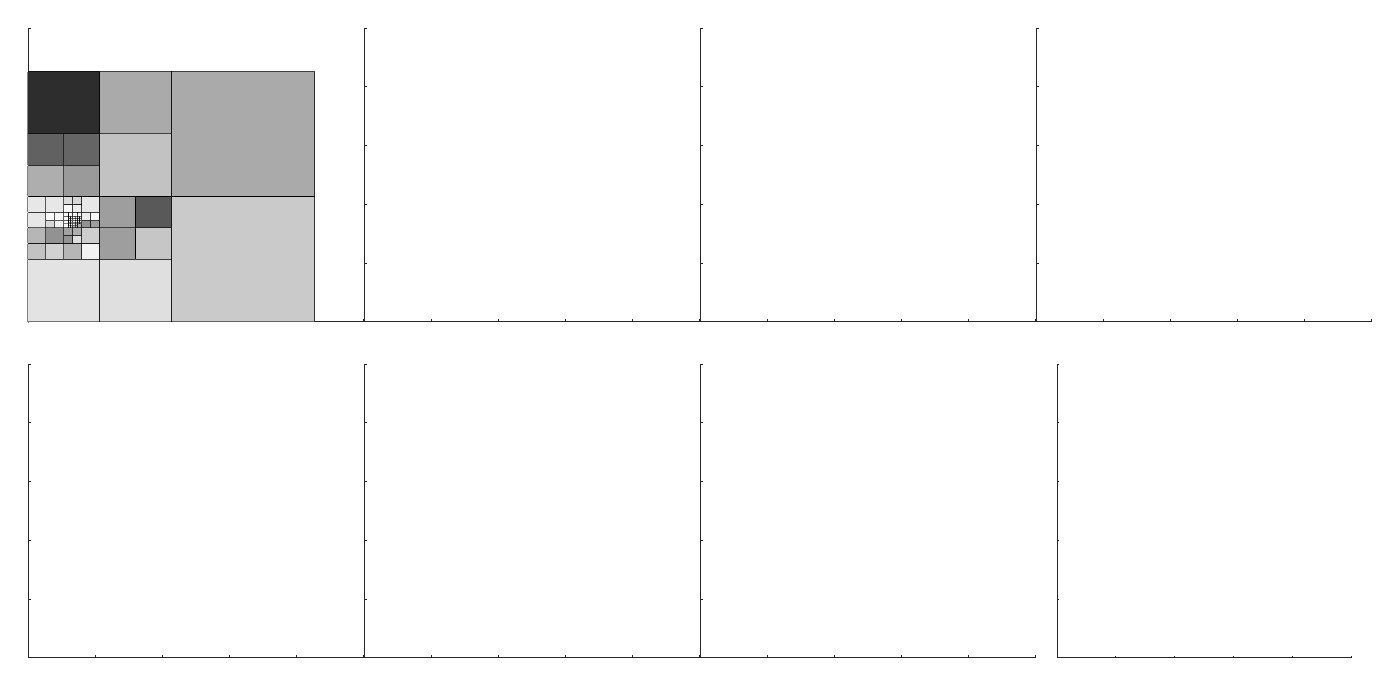

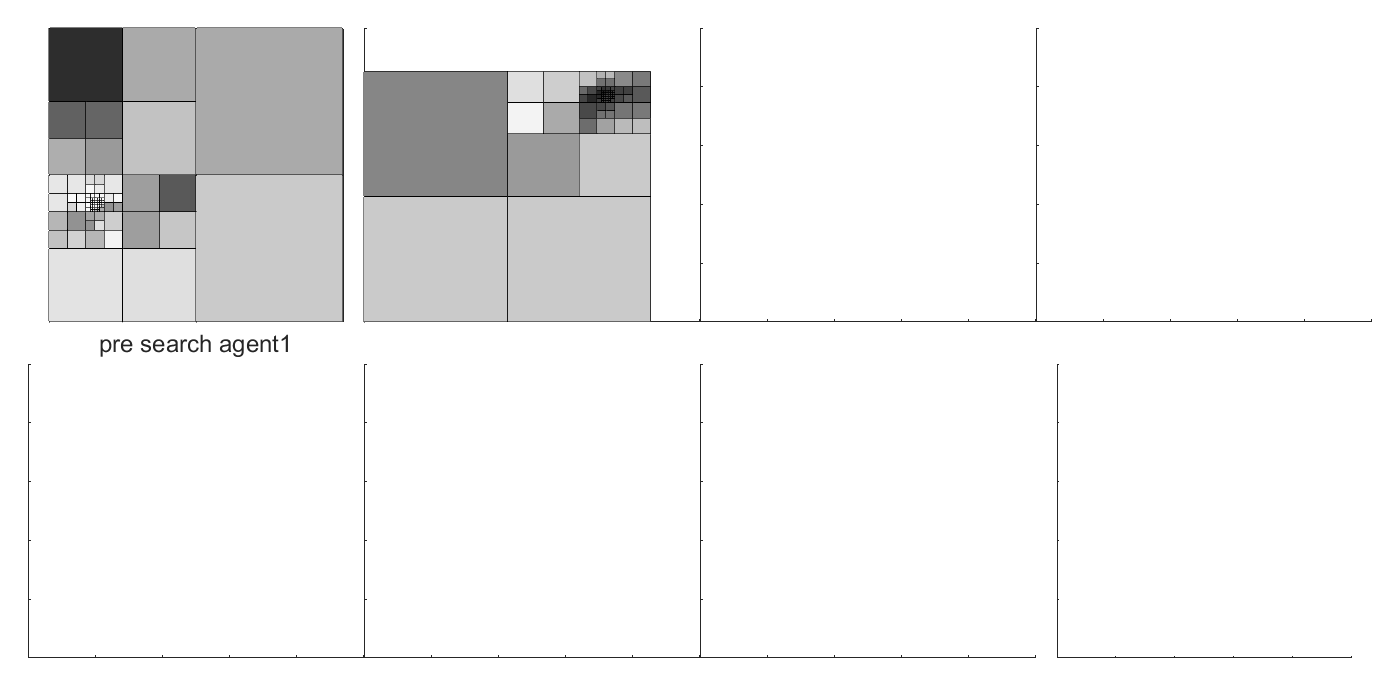

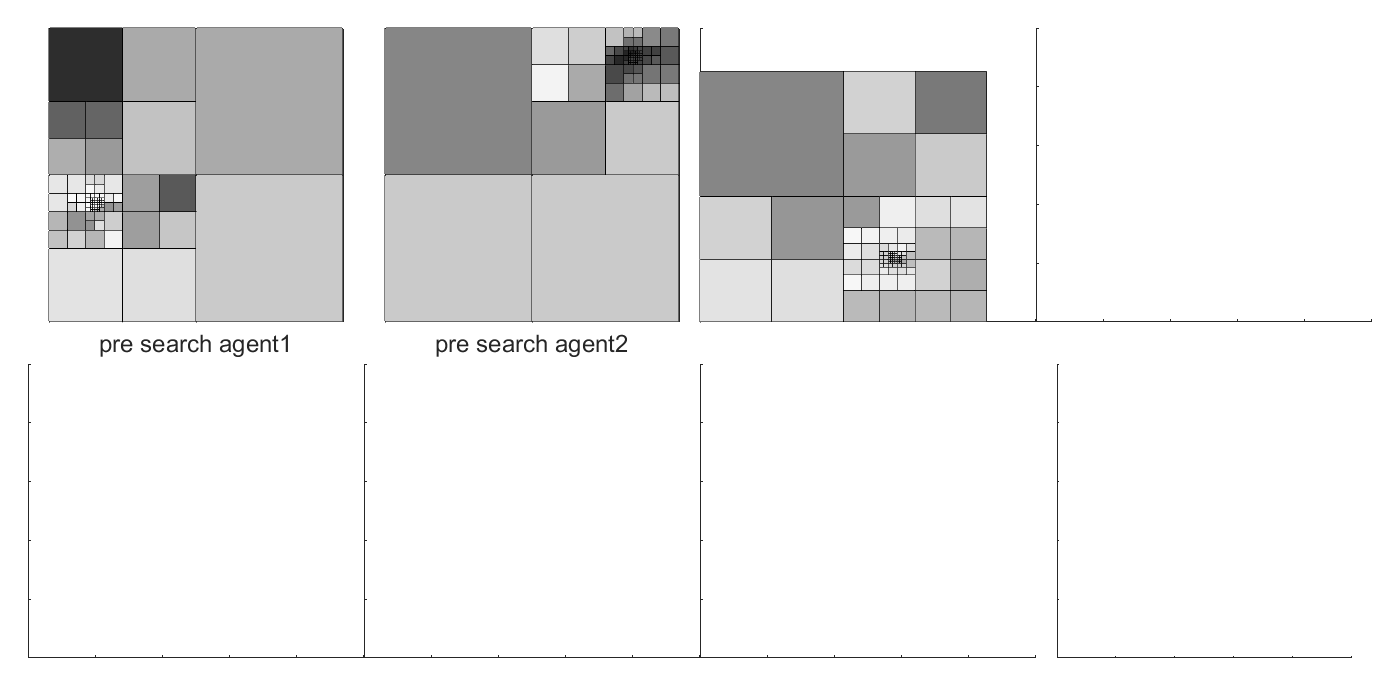

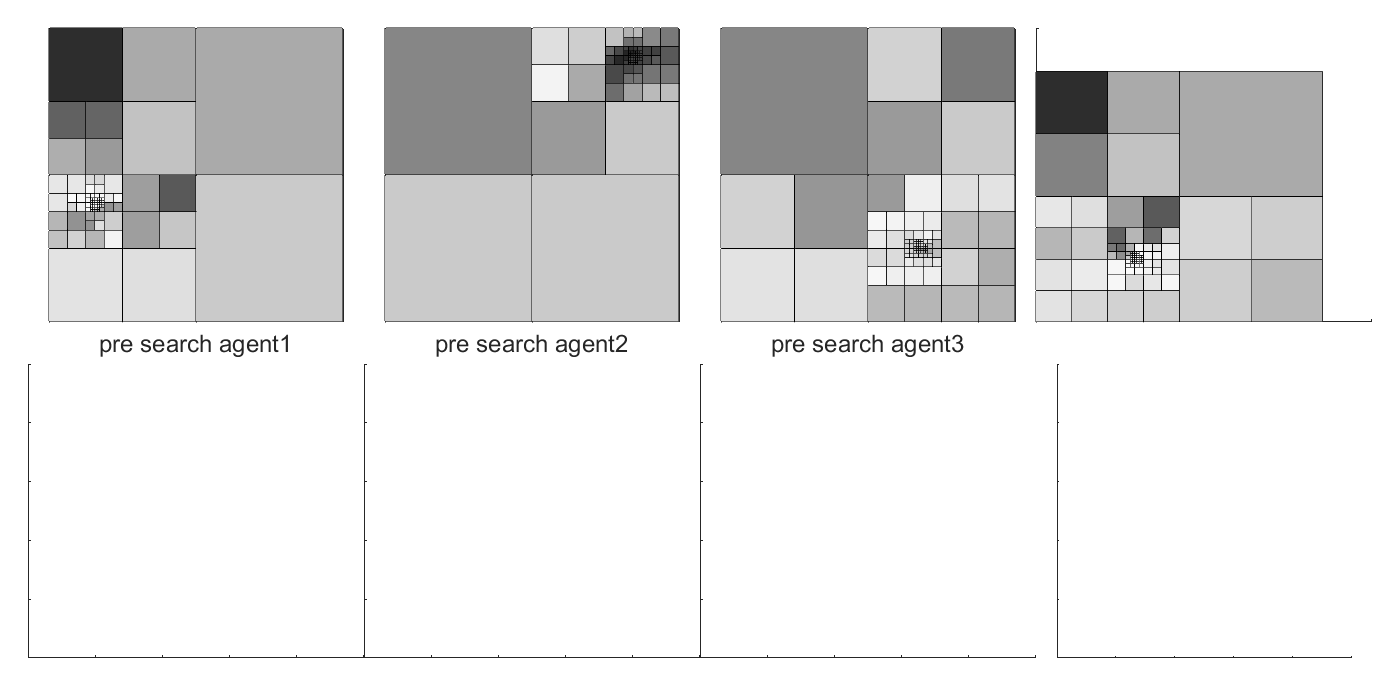

for agent_i=1:agent_number
 
    graph_file_name = ['instance/pre_graph', num2str(agent_i),'.txt'];    
    graph = load(graph_file_name);
    
    if (drawPrePath)
    path_file_name = ['instance/pre_path', num2str(agent_i),'.txt'];
    end

    vertices= graph(:,1:3);
    values = graph(:, 4);    
    edges = graph(:, 5:end);
    
    if (sum(values>1))
        exceed = values(values>1);
        fprintf('WARNING: agent %d value exceed 1 : %f\n',agent_i, exceed(1) )
        values(values>1)= 1;  
    end

   
    if(pdfy)
        my_axis = ha(agent_i); axis tight; axis equal; 
        axes(my_axis); hold on;
    else
        subplot(2, agent_number,agent_i); axis tight; axis equal; 
    end
    num_vert = size(vertices,1);
    for i=1:num_vert
        v_size = vertices(i,3);
        if v_size~=0

            if drawValue
                val_color = color_bar( (ceil(values(i)*(color_bit-1)) +1),: );
                rectangle('Position', [vertices(i,1)-v_size/2, vertices(i,2)-v_size/2, v_size,v_size], 'Curvature', 1/v_size, 'FaceColor',val_color);
            else
                rectangle('Position', [vertices(i,1)-v_size/2, vertices(i,2)-v_size/2, v_size,v_size], 'Curvature', 1/v_size);
            end

            if drawText
                text('Position',[vertices(i,1)-v_size/3, vertices(i,2)-v_size/3],'string',num2str(i-1));
            end

            if drawEdge
                edge_from_i = edges(i,:);    
                for j=find(edge_from_i) %nonzero elements
                    point_a= [vertices(i,1), vertices(edge_from_i(j),1)];
                    point_b= [vertices(i,2), vertices(edge_from_i(j),2)];
                    line( point_a, point_b, 'linewidth',1.2);
                end
            end
        end
    end

## draw path

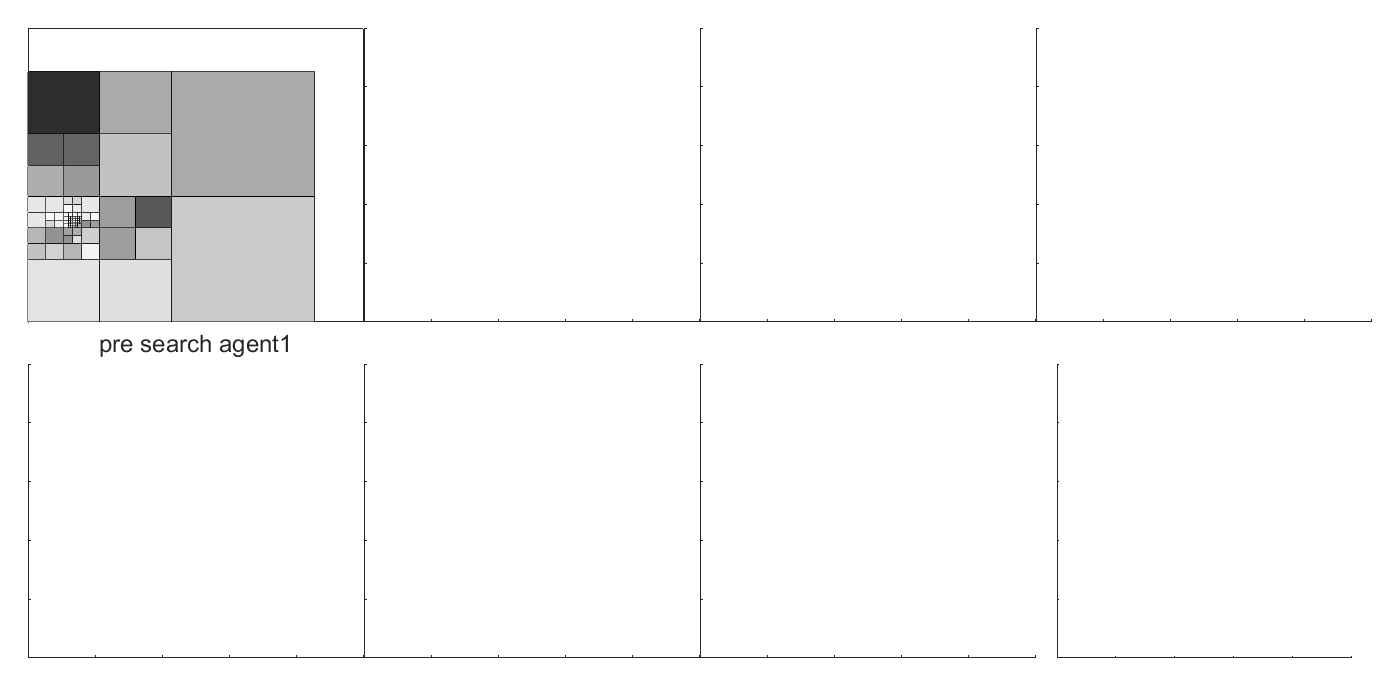

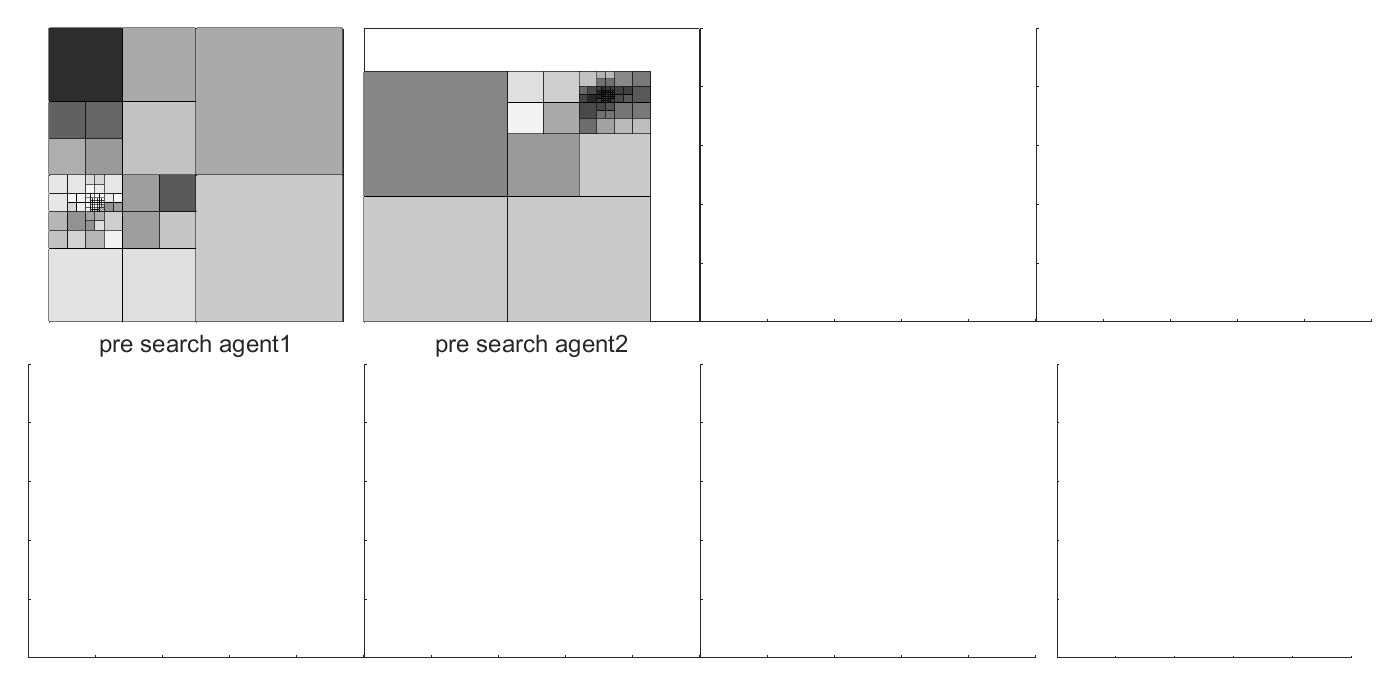

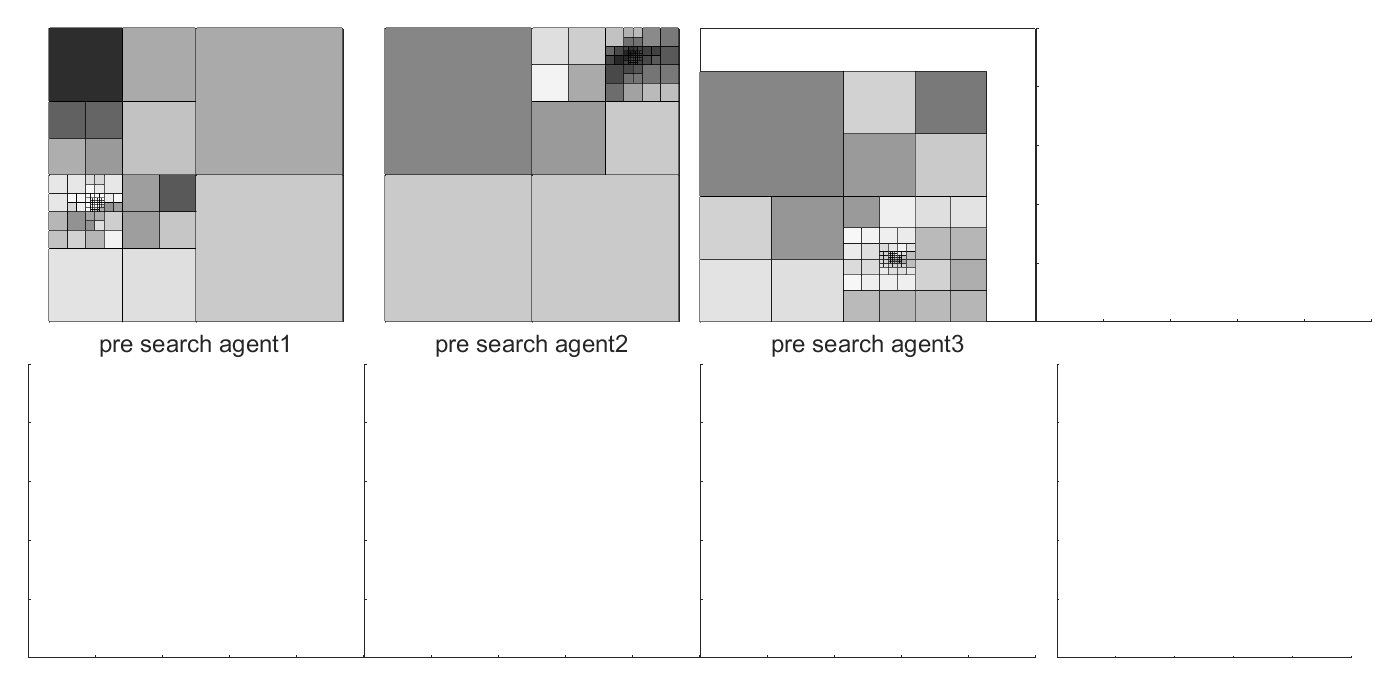

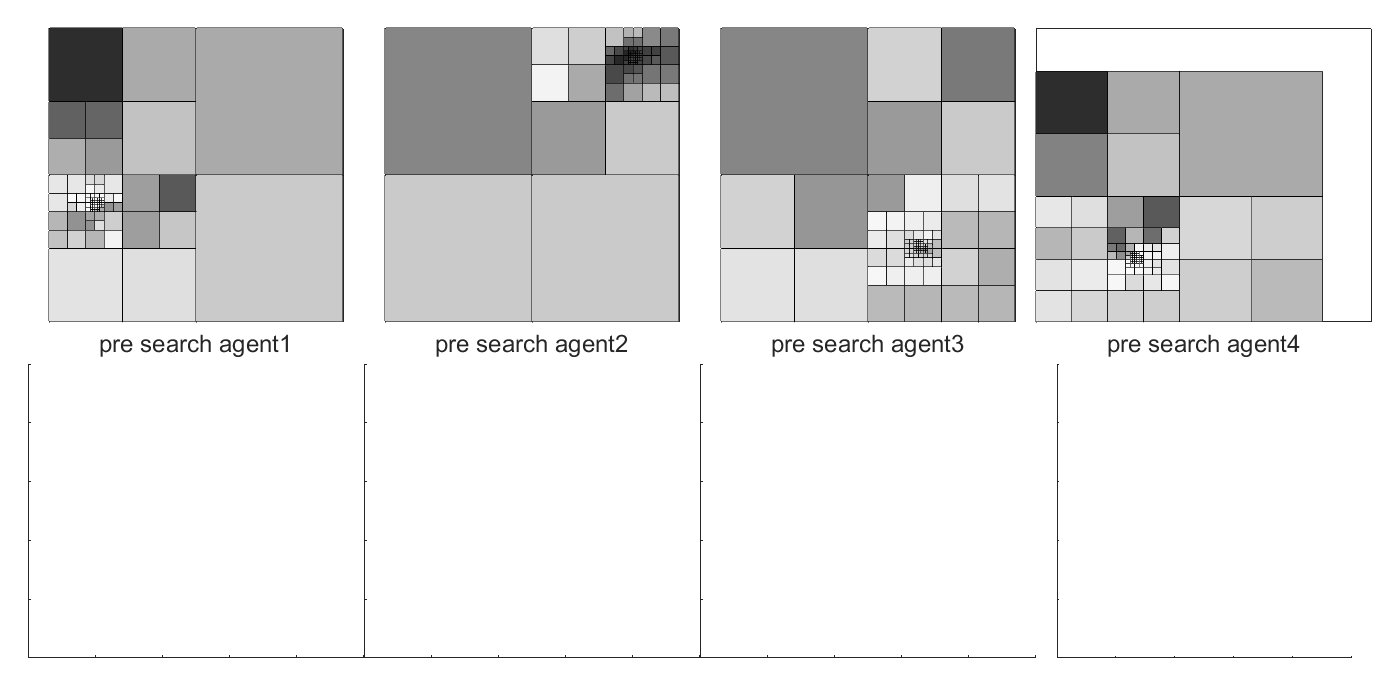

    if(drawPrePath)
        path = load(path_file_name);
        path = path+1;
        for i=1:length(path)
            v_size = vertices(path(i),3);
            if v_size~=0
                if i==1
                     rectangle('Position', [vertices(path(i),1)-v_size/2, vertices(path(i),2)-v_size/2, v_size,v_size], 'Curvature', 1/v_size,...
                    'EdgeColor',[.5 0 .5],'LineWidth',3);
                else
                     rectangle('Position', [vertices(path(i),1)-v_size/2, vertices(path(i),2)-v_size/2, v_size,v_size], 'Curvature', 1/v_size,...
                    'EdgeColor',[0 .5 .5],'LineWidth',3);

                end

            end
        end
    end
    
    
    drawnow;
%     xl=xlabel(['pre search $\mathcal{G}$', num2str(agent_i)] );
%     set(xl,'FontSize',18, 'Interpreter', 'LaTex');
    xl=xlabel(['pre search agent', num2str(agent_i)] );
    set(xl,'FontSize',18);
    ax = gca;
    newticks = 0:4:ax.XAxis.Limits(2);
    ax.XAxis.TickValues = newticks;
    ax.YAxis.TickValues = newticks;
    if(pdfy)
        set(gca,'xtick',[]);
        set(gca,'ytick',[]);

        box on;
    end

end %% for agent_number

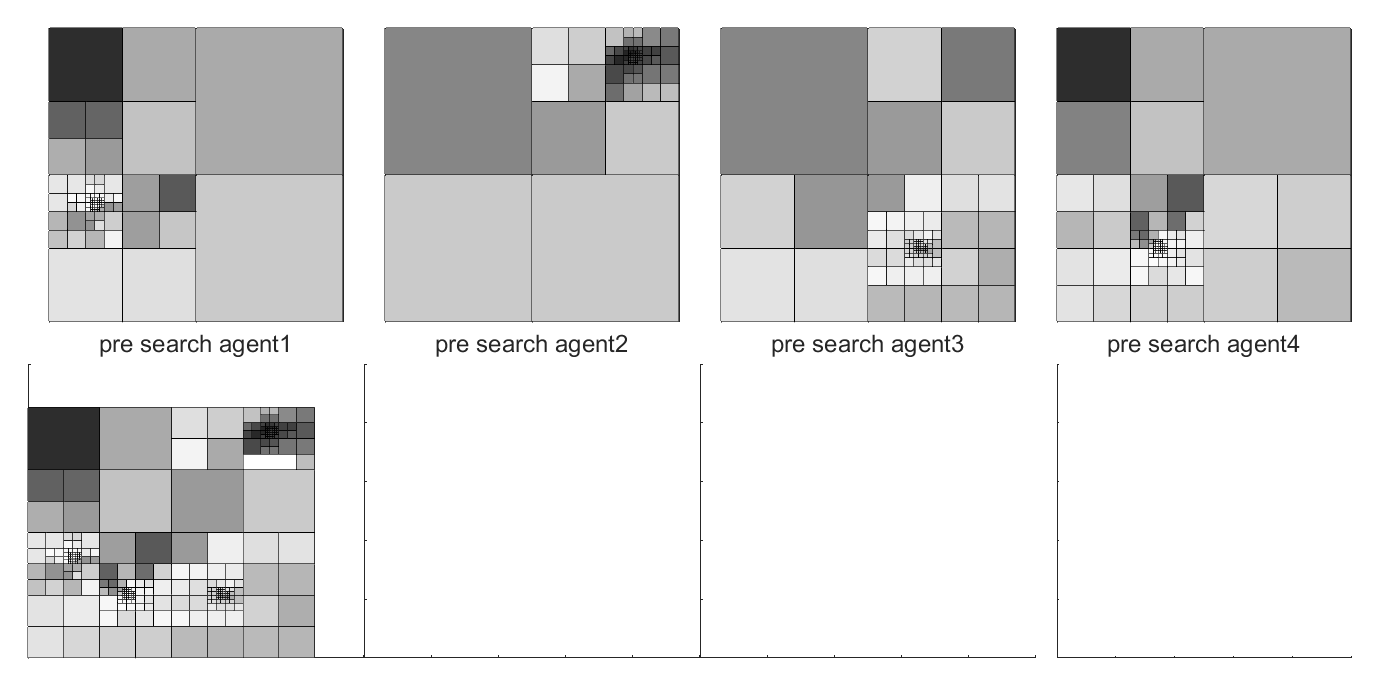

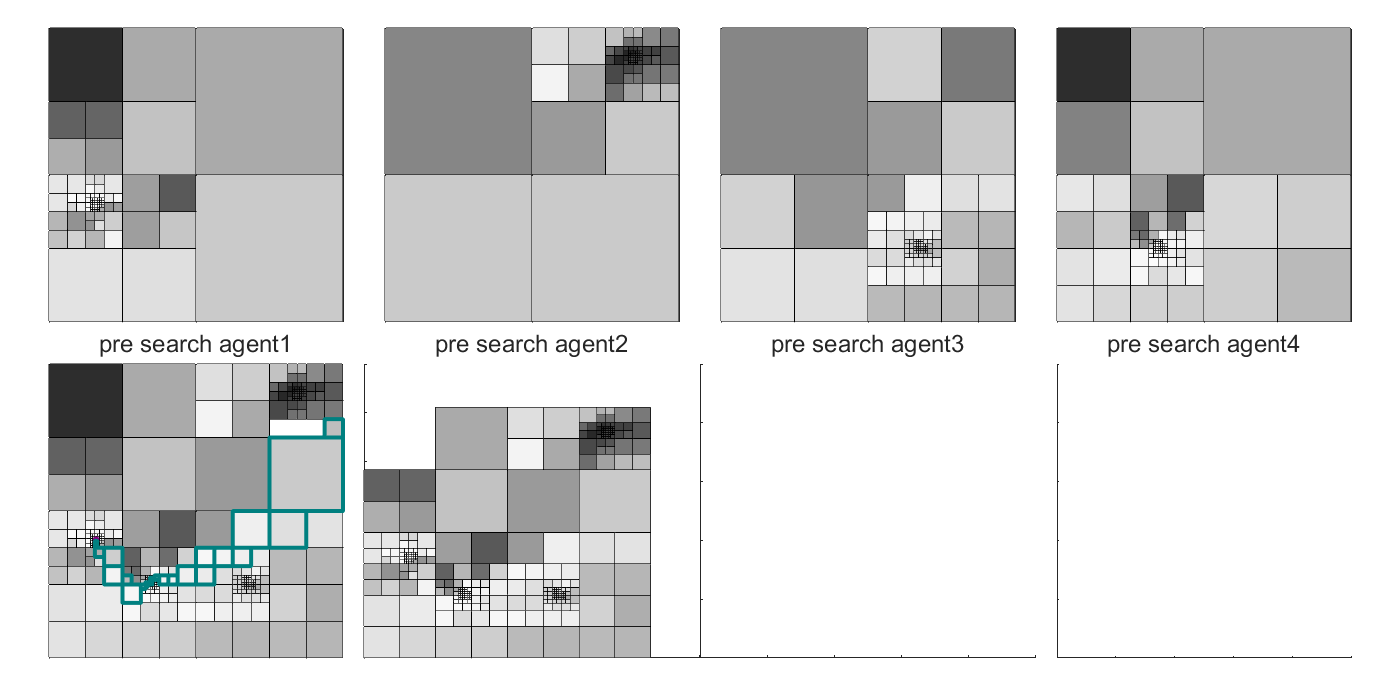

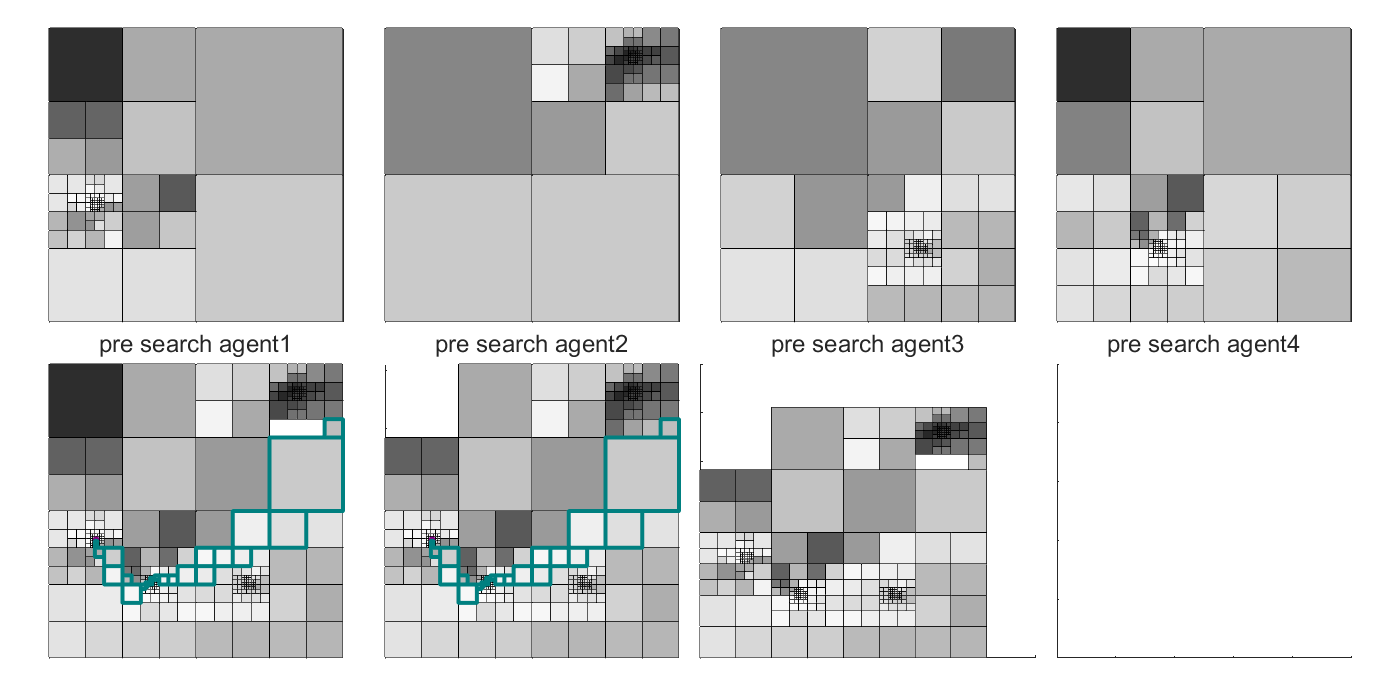

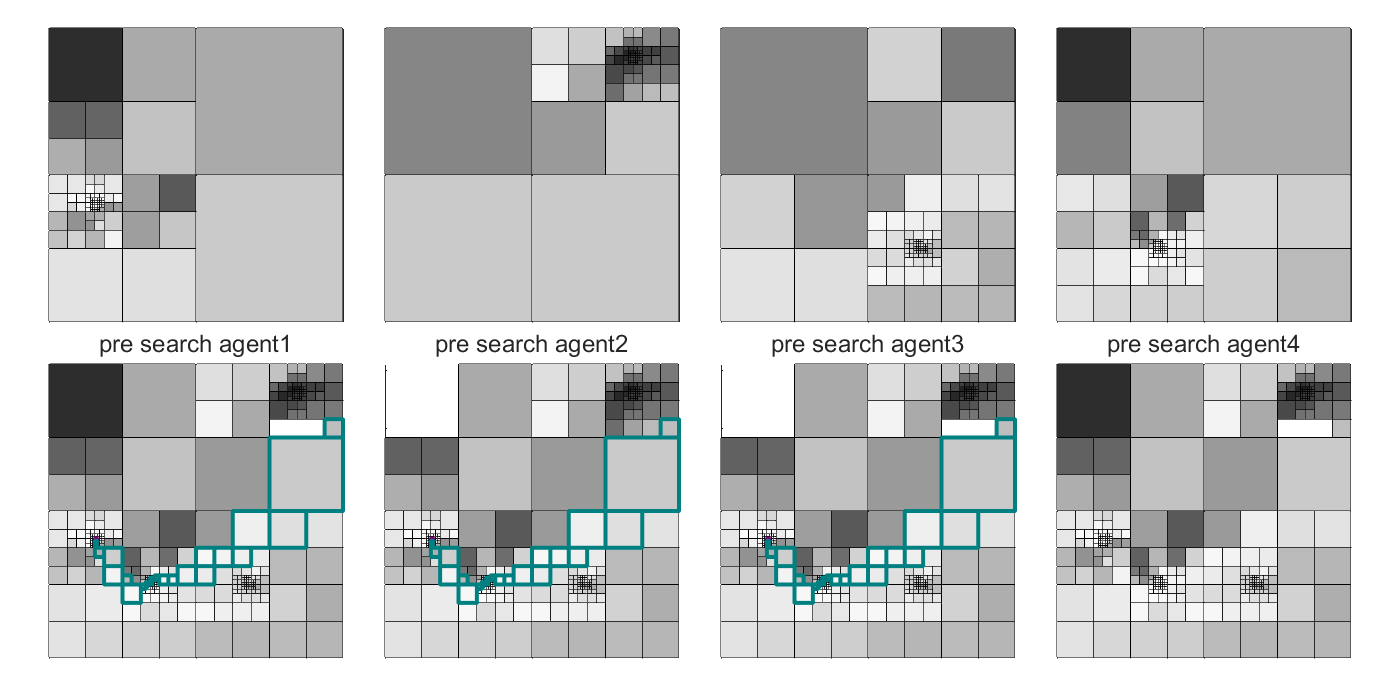

if (drawPostSearch )
for agent_i=1:agent_number
    graph_file_name = ['instance/graph', num2str(agent_i),'.txt'];
    path_file_name = ['instance/path', num2str(agent_i),'.txt'];

    graph = load(graph_file_name);

    if(pdfy)
        my_axis = ha(agent_i+agent_number); axis tight; axis equal; 
        axes(my_axis); hold on;
    else
        subplot(2, agent_number,agent_i+agent_number); axis tight; axis equal; 
    end
    
    vertices= graph(:,1:3);
    values = graph(:, 4);
    edges = graph(:, 5:end);
    
    if (sum(values>1))
        exceed = values(values>1);
%         fprintf('WARNING: agent %d value exceed 1 : %f\n',agent_i, exceed(1) )
        values(values>1)= 1;  
    end


    num_vert = size(vertices,1);
    for i=1:num_vert
        v_size = vertices(i,3);
        if v_size~=0

            if drawValue
                val_color = color_bar( (ceil(values(i)*(color_bit-1)) +1),: );
                rectangle('Position', [vertices(i,1)-v_size/2, vertices(i,2)-v_size/2, v_size,v_size], 'Curvature', 1/v_size, 'FaceColor',val_color);
            else
                 rectangle('Position', [vertices(i,1)-v_size/2, vertices(i,2)-v_size/2, v_size,v_size], 'Curvature', 1/v_size);
            end

            if drawText
                text('Position',[vertices(i,1)-v_size/3, vertices(i,2)-v_size/3],'string',num2str(i-1));
            end

            if drawEdge
                edge_from_i = edges(i,:);    
                for j=find(edge_from_i) %nonzero elements
                    point_a= [vertices(i,1), vertices(edge_from_i(j),1)];
                    point_b= [vertices(i,2), vertices(edge_from_i(j),2)];
                    line( point_a, point_b, 'linewidth',1.2);
                end
            end
        end
    end

## draw path

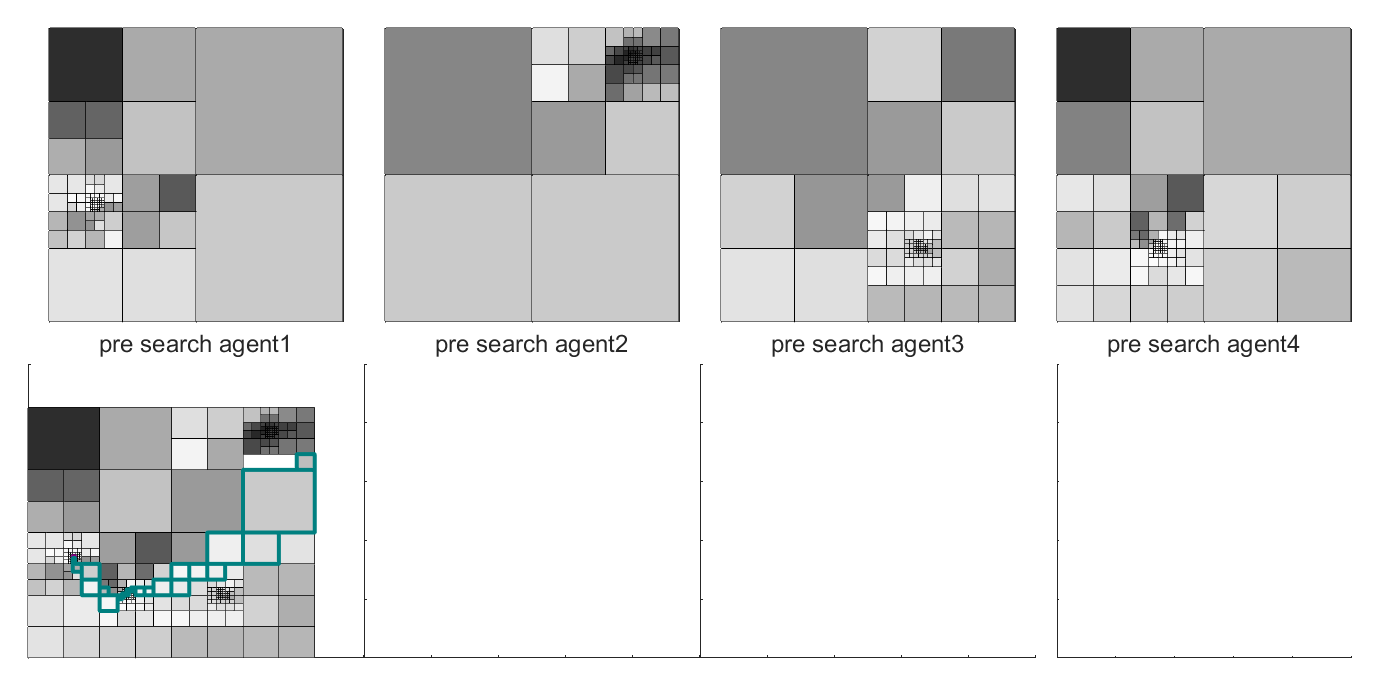

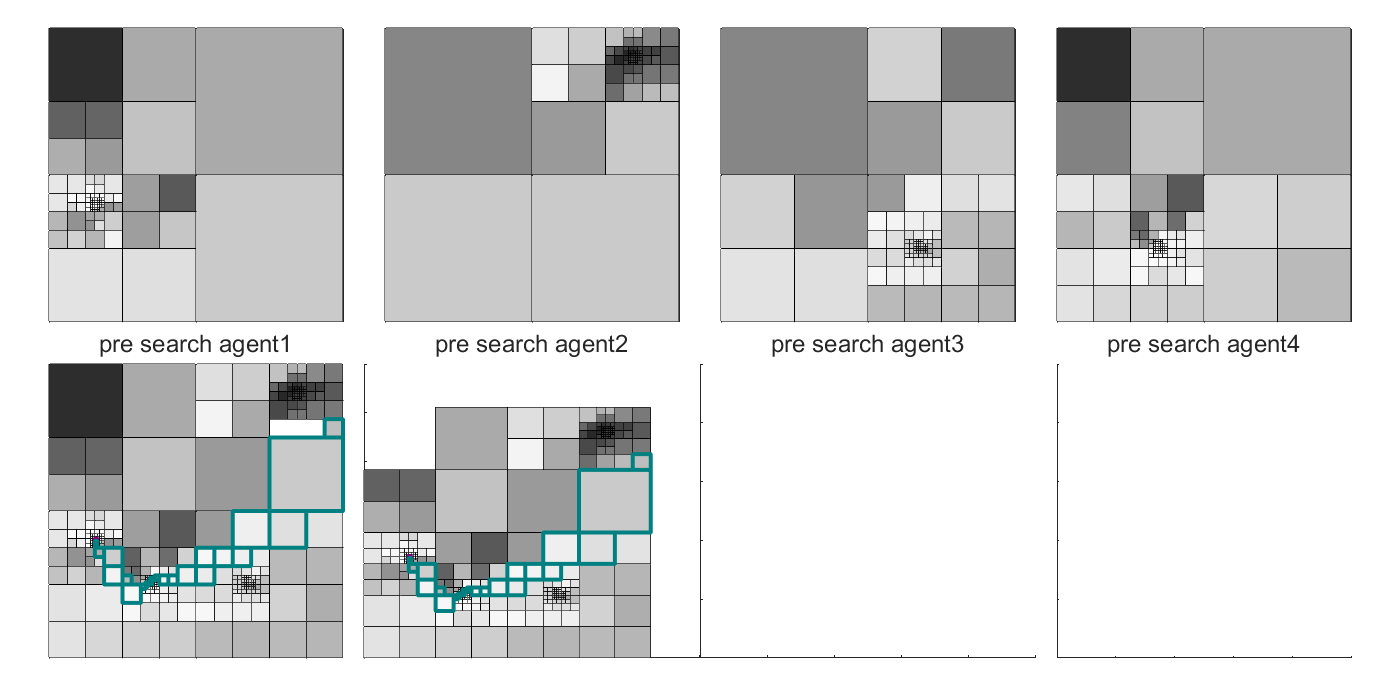

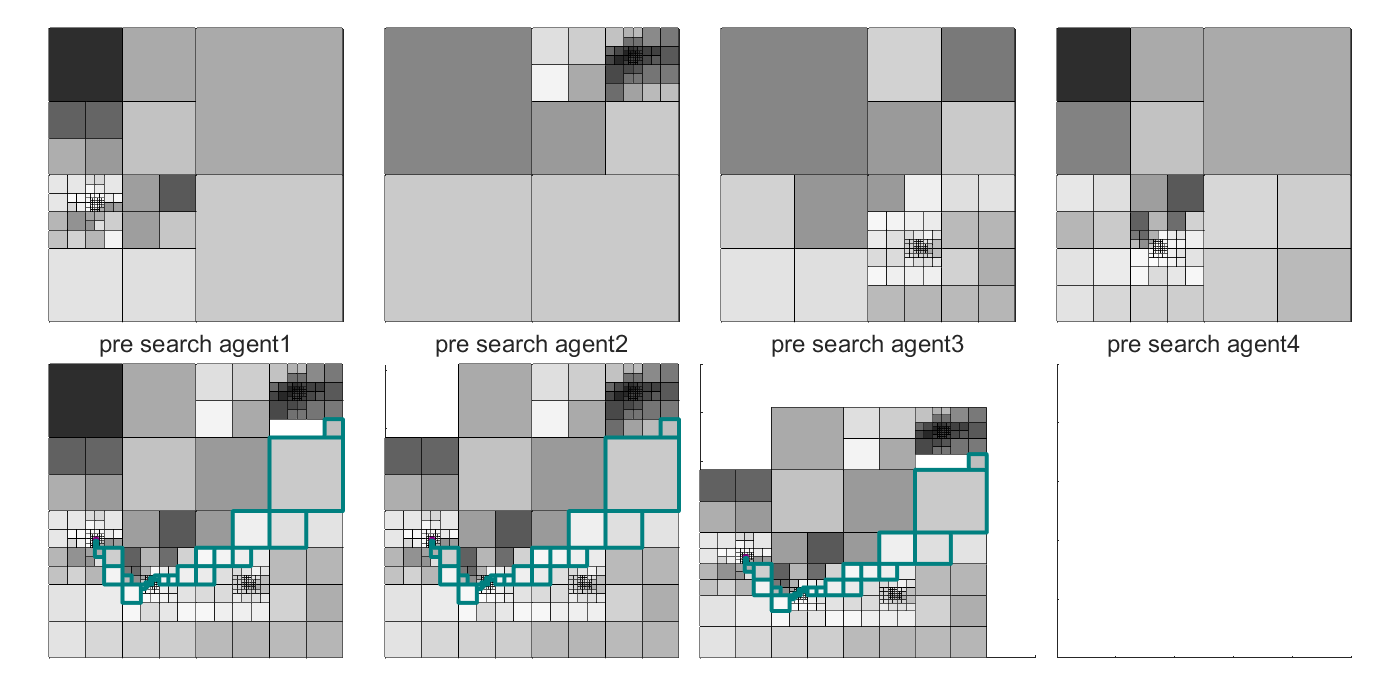

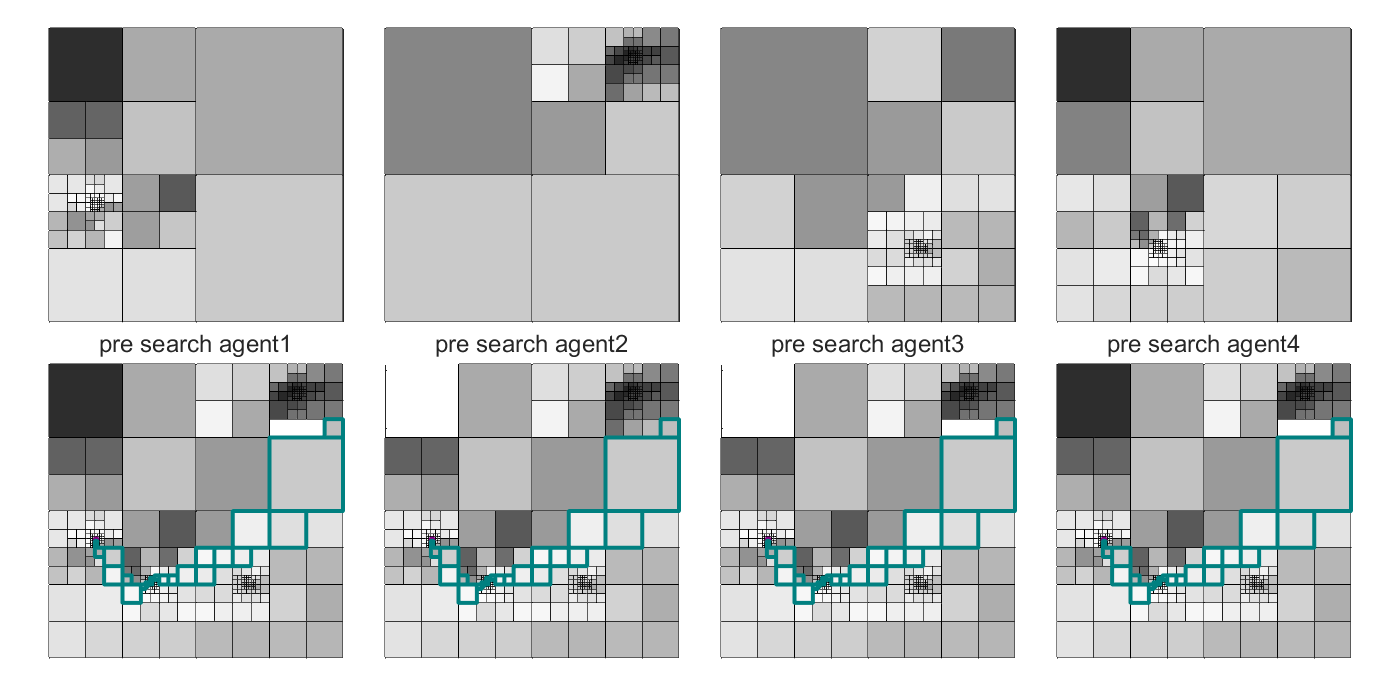

    if(drawPath)
        path = load(path_file_name);
        path = path+1;
        for i=1:length(path)
            v_size = vertices(path(i),3);
            if v_size~=0
                if i==1
                     rectangle('Position', [vertices(path(i),1)-v_size/2, vertices(path(i),2)-v_size/2, v_size,v_size], 'Curvature', 1/v_size,...
                    'EdgeColor',[.5 0 .5],'LineWidth',3);
                else
                     rectangle('Position', [vertices(path(i),1)-v_size/2, vertices(path(i),2)-v_size/2, v_size,v_size], 'Curvature', 1/v_size,...
                    'EdgeColor',[0 .5 .5],'LineWidth',3);

                end

            end
        end
    end

    drawnow;
%     xl=xlabel(['post search $\mathcal{G}$', num2str(agent_i)] );
%     set(xl,'FontSize',18, 'Interpreter', 'LaTex');
    xl=xlabel(['post search agent', num2str(agent_i)] );
    set(xl,'FontSize',18);
    ax = gca;
    newticks = 0:4:ax.XAxis.Limits(2);
    ax.XAxis.TickValues = newticks;
    ax.YAxis.TickValues = newticks;
    if(pdfy)
        set(gca,'xtick',[]);
        set(gca,'ytick',[]);
        box on;
    end
end %% for agent_number
end